inp = readtable("g_edges.csv");
all_names = [inp.Source; inp.Target];
all_names = unique(all_names);

s_1 = inp.Source'; s_1 = string(s_1);
t_2 = inp.Target'; t_2 = string(t_2);


Graph = digraph(s_1,t_2,(double(inp.Weight))');
deg_gr = indegree(Graph);
size_v = 2.*sqrt(deg_gr-min(deg_gr))+0.2;


       Name       deg_gr
    __________    ______

    {'TYRION'}      37  
    {'NED'   }      34  
    {'ROBERT'}      28  
    {'SANSA' }      22  
    {'ROBB'  }      21  



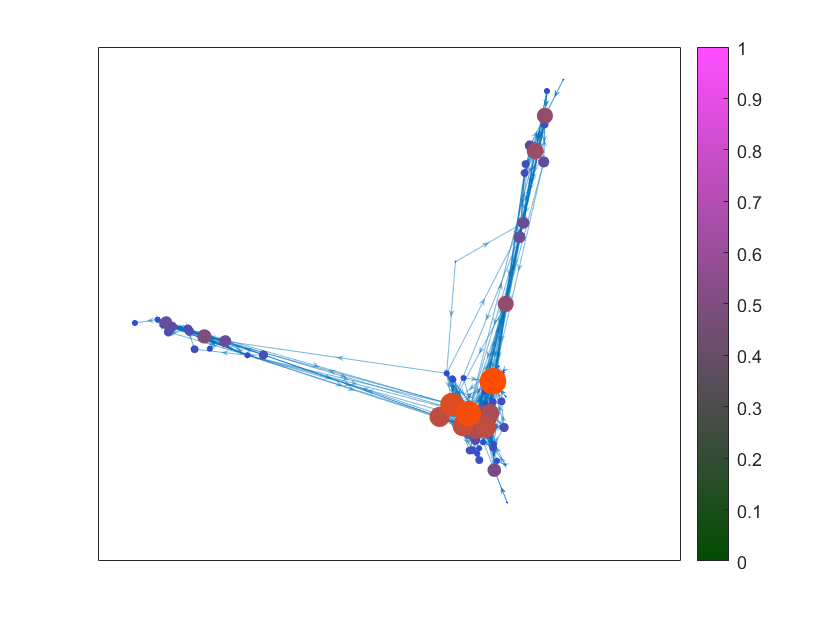


colour = zeros(length(all_names),3);
for i=1:length(all_names)
    col = size_v(i)/max(size_v);
    colour(i,1) = col;
    colour(i,2) = 0.3;
    colour(i,3) = 1-col;
end

plot(Graph,'MarkerSize',size_v,'NodeColor',colour);
xlim([-2.48 5.69]);
ylim([-5.52 2.28]);
colormap([linspace(0,1,256);0.3*ones(1,256);linspace(0,1,256)]');
colorbar;

xlim([-5.01 3.16])
ylim([-2.71 5.09])



tops = sortrows([Graph.Nodes array2table(deg_gr)],2,'descend');
top = tops(1:5,:);
disp(top);


disp(shortestpath(Graph,'NED','TYRION'));

    {'NED'}    {'PYP'}    {'TYRION'}

